# HMM Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

Figflag = 0;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/embryo6/'];
mkdir(FigPath)

Now, load all the data

load('./data/hmm_input_output.mat')

Specify some parameters

numParticle = length(hmm_input_output);
TimeOffset = 11.31;

% Specify the bins we want to plot
binRange = 61:66; % 61-66 

## Part 2: Fliter traces including quality control

First, we want to filter the traces based on SetID

dataID = 2; % We want to analyze "optoknirps_new_embryo6"
SetID_all = [hmm_input_output(:).SetID]; % SetID for all the traces
%TraceIndex = find(SetID_all == dataID); % Trace index that we will analyze

Then, we can assign the traces to each AP bin

APbinID = linspace(0,100,101);
APPosition_mean = zeros(numParticle,1);

for i = 1:numParticle
    APPosition_mean(i) = mean(hmm_input_output(i).APPosition);
end

APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);

LeftBound = 5;
RightBound = 15;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

## Part 3: Plot traces

Let's plot some traces

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

for i = TraceIndex
    ParticleID = hmm_input_output(i).ParticleID;
    SpotTime = hmm_input_output(i).Time/60-TimeOffset; % convert to min

    if Figflag
        p = i;
        fluo_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).SpotFluorescence,'LineWidth',1.5)
        plot(SpotTime,hmm_input_output(p).FluoViterbi,'--','LineWidth',1.5)
        ylabel('spot fluorescence (au)')
        ylim([0 3E5])
        
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 8E5])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        saveas(fluo_fig,[FigPath 'particle' num2str(ParticleID) '_fluo_plot.png'])
        
        v_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).InitiationRate,'LineWidth',1.5)
        stairs(SpotTime,hmm_input_output(p).PromoterState,'-','LineWidth',1.5)
        ylim([0 3E3])
        
        ylabel('initiation rate')
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 8E5])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        saveas(v_fig,[FigPath 'particle' num2str(ParticleID) '_v_plot.png'])
    end
end

## Part 4: Find threshold value

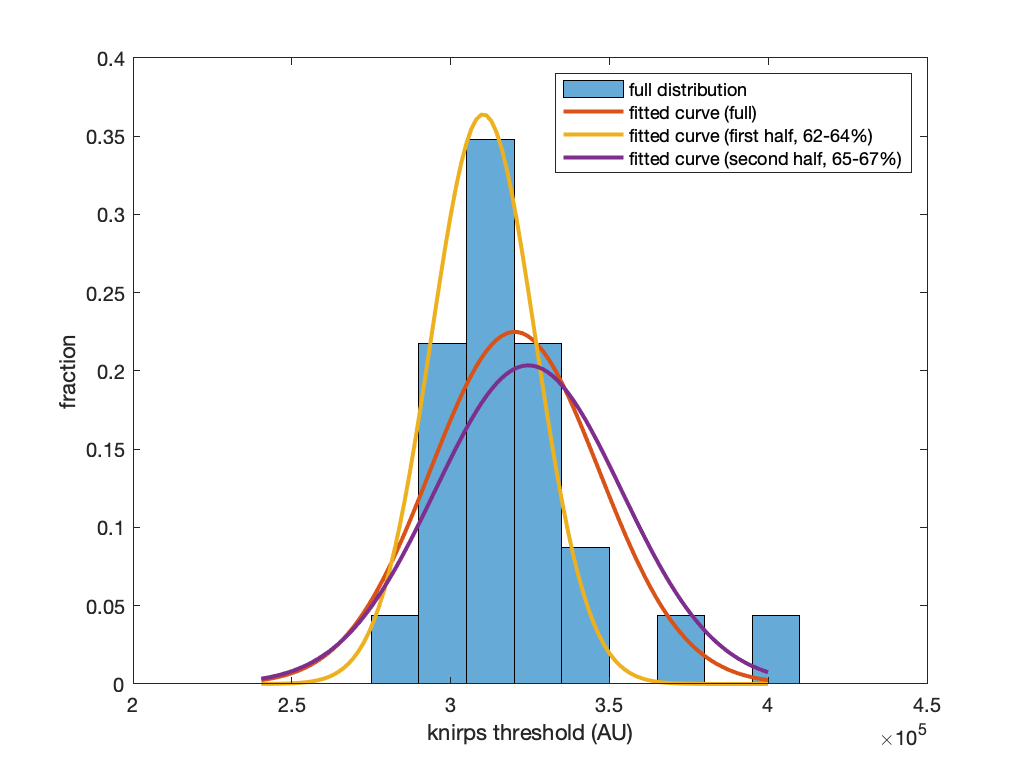

binRange_1 = 61:63;
binRange_2 = 64:66;

TraceIndex_1 = find((SetID_all == dataID) & (ismember(APbinData,binRange_1)') & QualityFlag');;
TraceIndex_2 = find((SetID_all == dataID) & (ismember(APbinData,binRange_2)') & QualityFlag');;

TimeOff_1 = [];
TimeOff_2 = [];
ProteinOff_1 = [];
ProteinOff_2 = [];

for i = TraceIndex_1
    side = 8;
    window = 2*side+1;
    
    PromState = hmm_input_output(i).PromoterState;
    PromState_mean = movmean(PromState,window);
    Index = min(find(PromState_mean<1.63));
    
    TimeOff_1 = [TimeOff_1 hmm_input_output(i).Time(Index-side)/60-TimeOffset];
    ProteinOff_1 = [ProteinOff_1 hmm_input_output(i).NuclearKnirps(Index-side)];
end

for i = TraceIndex_2
    side = 8;
    window = 2*side+1;
    
    PromState = hmm_input_output(i).PromoterState;
    PromState_mean = movmean(PromState,window);
    Index = min(find(PromState_mean<1.63));
    
    TimeOff_2 = [TimeOff_2 hmm_input_output(i).Time(Index-side)/60-TimeOffset];
    ProteinOff_2 = [ProteinOff_2 hmm_input_output(i).NuclearKnirps(Index-side)];
end

TimeOff = [TimeOff_1,TimeOff_2];
ProteinOff = [ProteinOff_1,ProteinOff_2];

proteinFigure = figure;

% Fit full distribution
data = ProteinOff;
dist = 'normal';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Fit partial distribution
data1 = ProteinOff_1;
dist = 'normal';
pd1 = fitdist(data1',dist);
% Find range for plotting
q1 = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution

data2 = ProteinOff_2;
dist = 'normal';
pd2 = fitdist(data2',dist);
% Find range for plotting
q2 = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution


% Do histogram calculations
edges = linspace(2E5,5E5,21);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);
y1 = area * pdf(pd1,x);
y2 = area * pdf(pd2,x);

% Overlay the density
hh = plot(x,y/n,'-','LineWidth',2);
hh1 = plot(x,y1/n,'-','LineWidth',2);
hh2 = plot(x,y2/n,'-','LineWidth',2);
legend('full distribution','fitted curve (full)','fitted curve (first half, 62-64%)', 'fitted curve (second half, 65-67%)')

%legend('full distribution')

%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('knirps threshold (AU)')
ylabel('fraction')

xlim([2E5 4.5E5])

%xlim([2E5 8E5])
%view(90, -90)

fig = figure

fig =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [256 178 512 384]
       Units: 'pixels'

  Show all properties


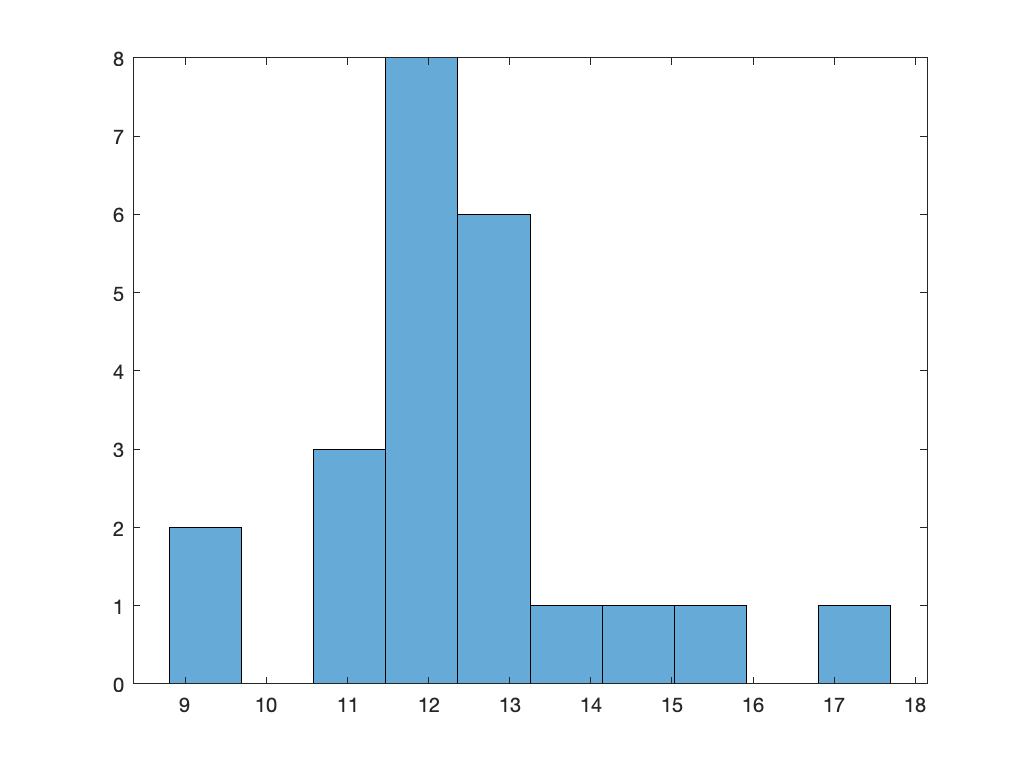

histogram(TimeOff,10)